## 初期化

cd(fileparts(matlab.desktop.editor.getActiveFilename)) % このmlxファイルがある場所に自動的に移動
addpath(genpath('./my_package/mylibrary'))
addpath(genpath('./my_package/matlab-treed'))
clc; clear; close all; clear variables

## シミュレーション条件

ts = 1e-2;
fs = 10;
e1=[1;0;0]; e2=[0;1;0]; e3=[0;0;1];

## 物理パラメータ

m = 0.938; %機体質量
g = 9.81;    % 重力加速度[m/s^2]

J_x = 0.00933; J_y = 0.00285; J_z = 0.01130;
J = diag([J_x;J_y;J_z]); %慣性テンソル(実験値)

## 制御器パラメータ

k_3 = 10; %速度フィードバックゲイン

K_p = diag([1,1]);
obst = "without_window"; %位置制御器

k_R = 3;
k_beta = 3;
k_p_gamma = 2;
k_d_gamma = 2; %姿勢制御器

## CBF-QP

y_c = 0.4; z_c = 1.5; r = 0.5; %障害物
% % alpha = 0.5;
% alpha_1 = 5;
% alpha_2 = 5;

## I-CBF

% gamma = 5;
% alpha = 1;
% z_dot_max =0.3;

## I-CBF(推力入力)

% gamma_x = 1;
% gamma_e = 1;

## I-CBF(高度方向以外も制御対象に含んだ推力入力のI-CBF)

% ノミナル入力にかかわるパラメータ
alpha = 30; %大きいと制約がない条件下で早くノミナル入力に近付く

% I-CBF全体に関わる制約
gamma_e = 10;

% 推力制約
gamma_u = 2; %大きいと攻めた入力制約
f_max = 20^2;

% 速度制約
gamma_x = 5; %大きいと攻めた状態制約
p_dot_zmax = 10;

% 位置制約
gamma_x1 = 4;
gamma_x2 = 4;
z_max = 1.5;

## 初期値

p_0= [0;0;0];
p_dot_0 = [0;0;0];

eta_0 = [0;0;0];
eta_dot_0 = [0;0;0];

## 目標値

p_d_0 = [0.1;0.3]; %y, zの2次元の位置目標値
% p_d_0 = [0;0.3]; %y, zの2次元の位置目標値
alpha_d = 0;
gamma_d = 10*pi/180; %姿勢目標値

## シミュレーションの実行

sim_action = 1;
if sim_action == 1  
    out = sim("euler_ZXY_model.slx");
end

## データの整理

position = out.logsout.getElement('position').Values;
velocity= out.logsout.getElement('velocity').Values;
attitude = out.logsout.getElement('attitude').Values;
desired_attitude = out.logsout.getElement('desired_attitude').Values;

eta_dot = out.logsout.getElement('eta_dot').Values;
thrust = out.logsout.getElement('thrust').Values;
torque = out.logsout.getElement('torque').Values;
body_velocity= out.logsout.getElement('body_velocity').Values;

p_d = out.logsout.getElement('p_d').Values;
figpath = 'figs';

## プロット

### データのプロット

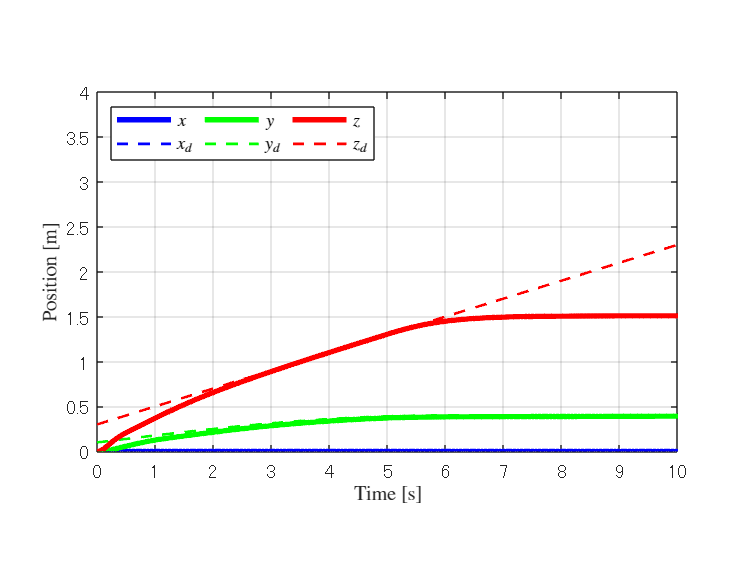

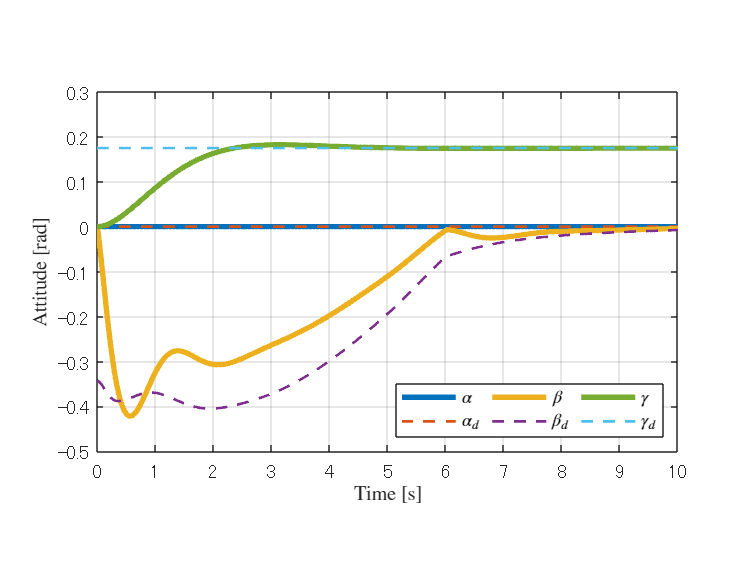

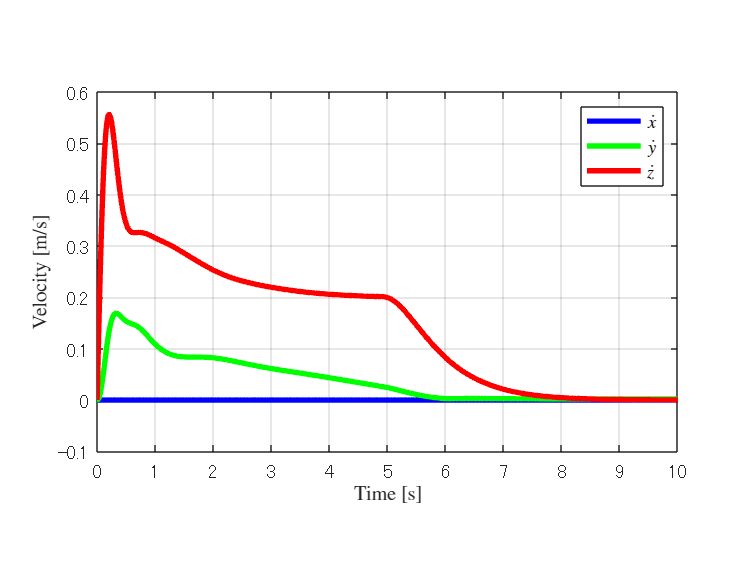

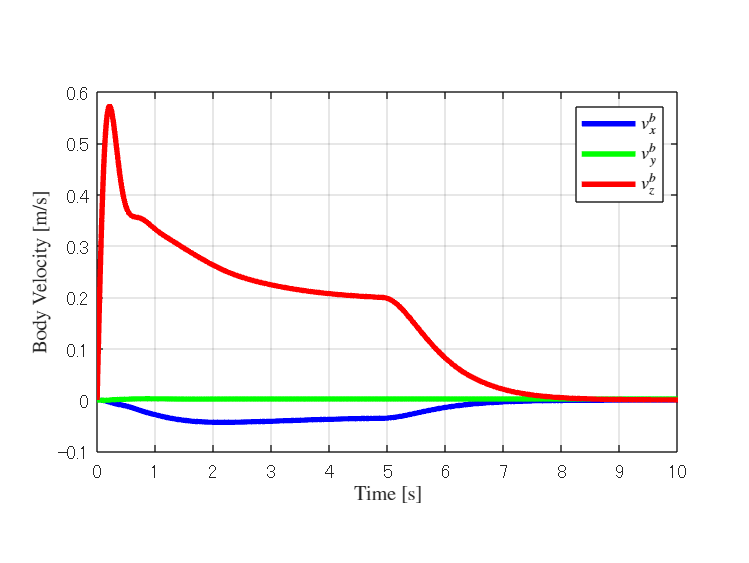

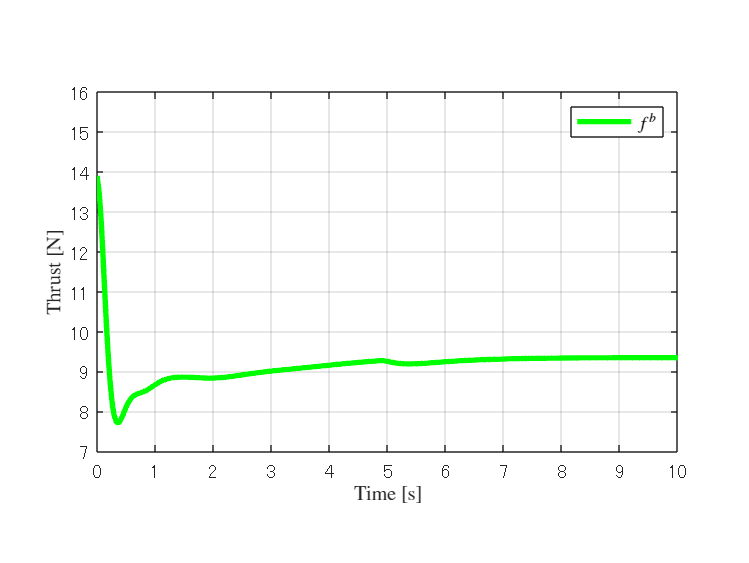

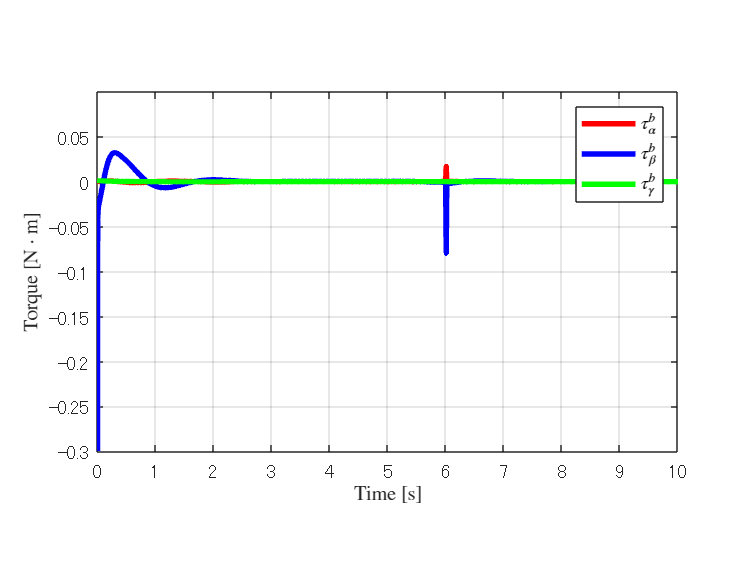

dataplot_action = 1;
if dataplot_action == 1
    run("data_plot.mlx")
end

### アニメーション

animation_unicycle = 0;
if animation_unicycle == 1
    run("animation.mlx")
end